# SNW_VFI_PARAM Tiny Solution Analysis

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function fully iteratively using matlab minimizer.

## Test SNW_VFI_MAIN Defaults

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
[V_VFI,ap_VFI,cons_VFI,exitflag_VFI] = snw_vfi_main(mp_param);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 73.404724 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_base


## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         -14.118                 -9.758             -6.587             -4.1655              -2.7048     
      2      0.068587         -10.475                -7.6844            -5.1246             -2.9746              -1.6159     
      3        0.5487         -2.9549                -2.3258            -1.5774            -0.69134              0.24233     
      4        1.8519         0.33712                0.45768             0.6411   

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         0.011833              0.031836            0.089931           0.20088               0.46185     
      2      0.068587         0.042291               0.06668             0.14585           0.24846                0.5052     
      3        0.5487          0.37391               0.37579             0.41283           0.60556               0.87798     
      4        1.8519           1.2791                1.2814              1.2891   

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     mean_shock__1_4213    mean_shock__0_71067    mean_shock_0    mean_shock_0_71067    mean_shock_1_4213
    _____    ________    __________________    ___________________    ____________    __________________    _________________

      1             0         0.21328                0.27374            0.37302            0.57536               0.94495     
      2      0.068587         0.29796                0.35348            0.43132            0.64179                1.0155     
      3        0.5487         0.76521                0.84173            0.96038             1.0798                1.4374     
      4        1.8519          2.0138                 2.0892             2.2362     

Graph Mean Values:

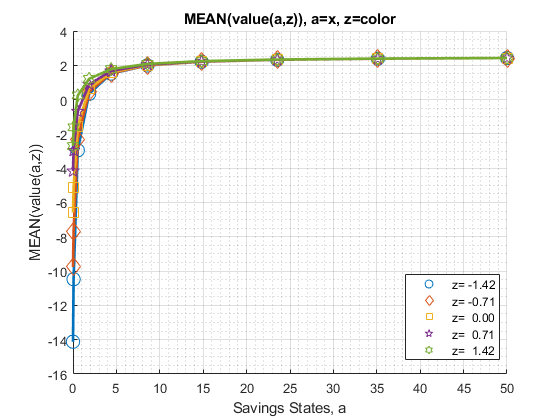

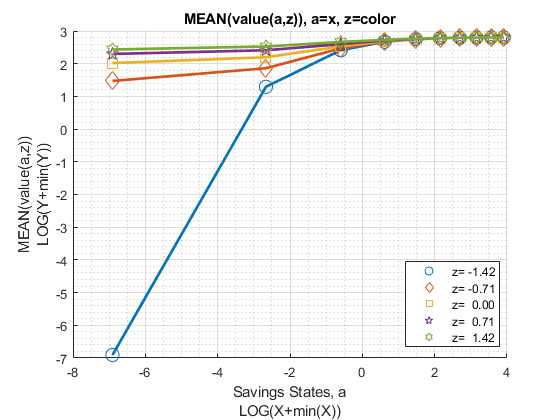

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

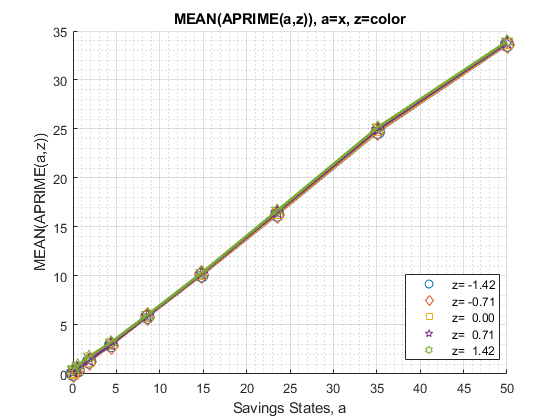

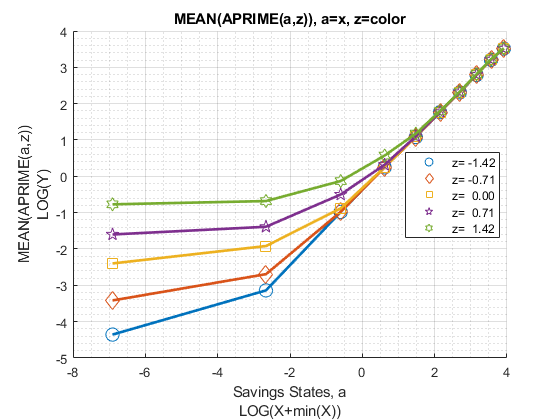

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Consumption:

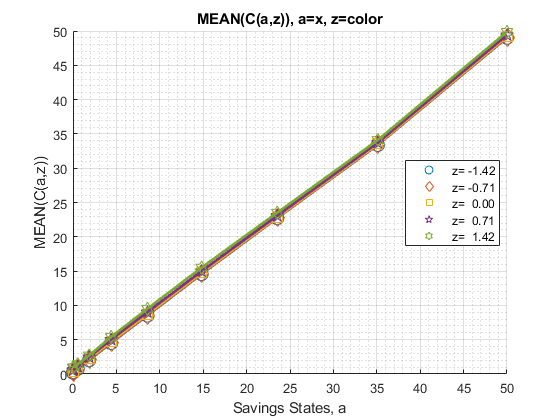

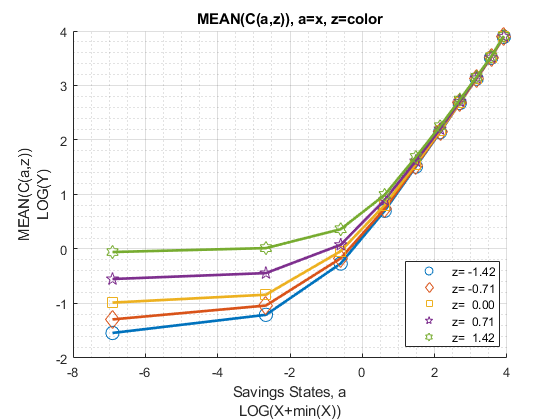

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0         1.0028        0.97835          0.875         0.53944      -0.082596       0.07178          0.1007  
      2       2        0        0.75355       0.093263        0.29247         0.11013       -0.55156      -0.30898        -0.27181  
      3       3        0       0.014837       -0.54118        -0.2695        

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        15.268         14.443         14.038         13.577         9.0943         2.7328            0      
      2       2        0        14.219         14.129         14.001         12.536         8.4692         2.3788            0      
      3       3        0        14.106         13.976         13.995         1

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0        8.3708         9.1952         9.8322         10.263         14.029         20.391          23.124   
      2       2        0        9.4191         9.5092         9.8695         11.303         14.654         20.745          23.124   
      3       3        0        9.5323         9.6623         9.8753         11

Graph Mean Values:

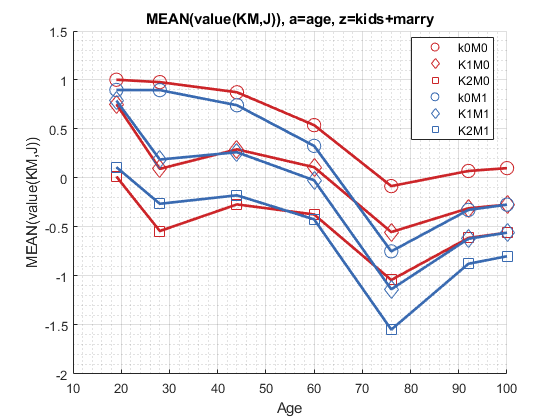

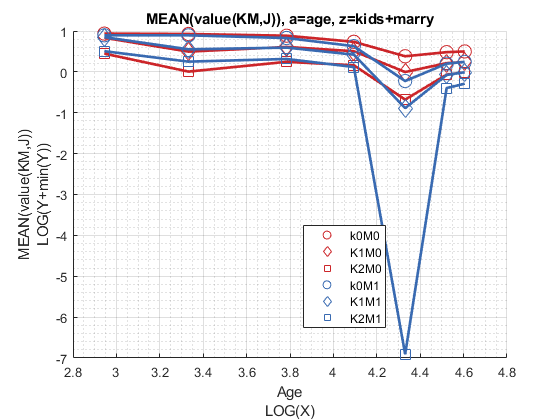

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

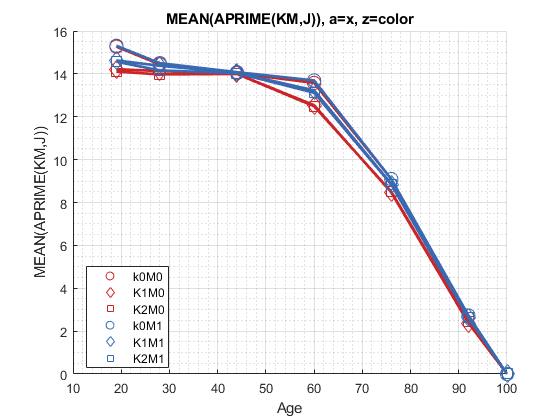

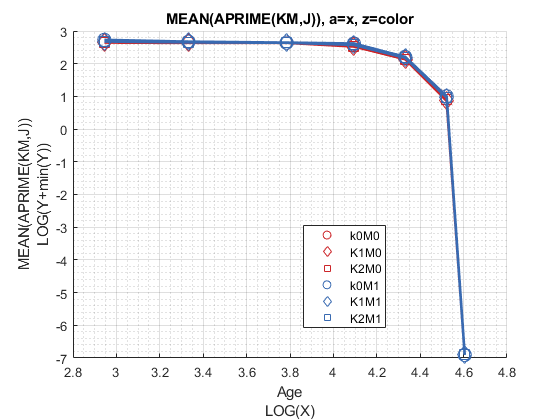

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

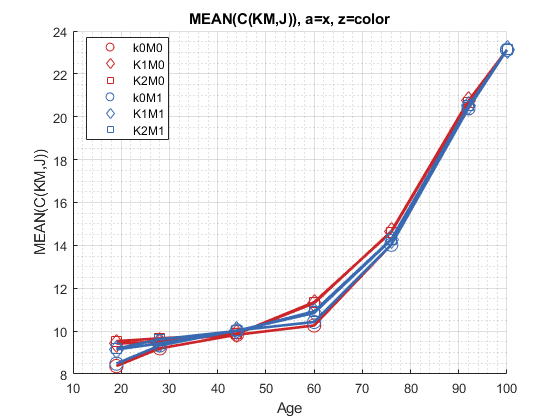

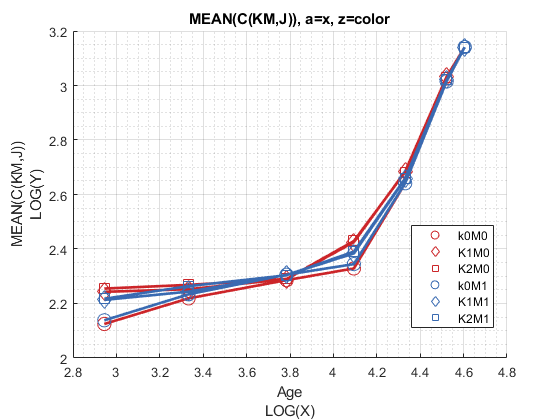

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        0.19635        -0.19792      0.0012171      -0.11754       -0.69061       -0.36563        -0.32094  
      2       1       0        0.98442         0.55154        0.59744       0.30249       -0.42582       -0.20035        -0.16489  
      3       0       1        0.21412       -0.079069      -0.010017      -0.25

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        14.519         14.178         13.977         12.802          8.695         2.5298            0      
      2       1       0        14.543         14.188         14.046         12.933         8.6827         2.5041            0      
      3       0       1         14.82         14.335         14.011         13.27

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       0       0        9.0312         9.3721          9.731         10.891         14.411         20.576          23.106   
      2       1       0        9.1836         9.5391         9.9869         11.055         14.459         20.638          23.142   
      3       0       1        8.8492         9.3616         9.8765         10.629

Graph Mean Values:

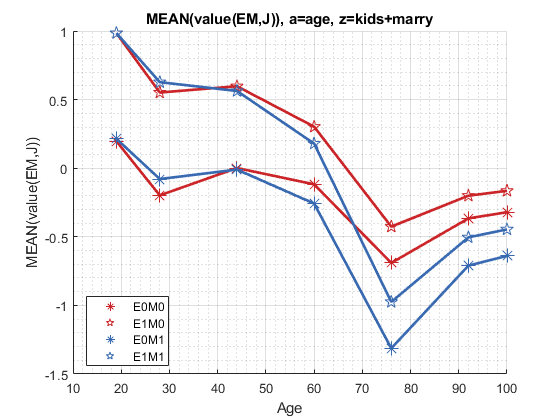

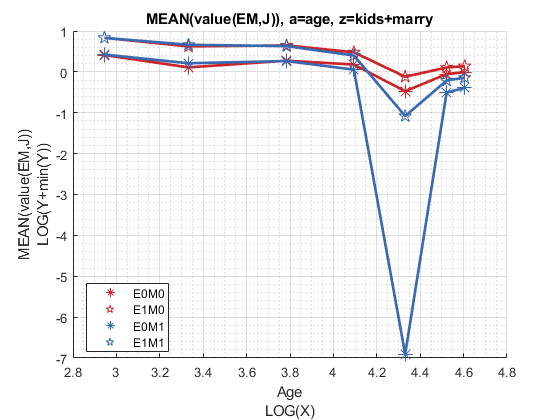

mp_support_graph('cl_st_graph_title') = {'MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

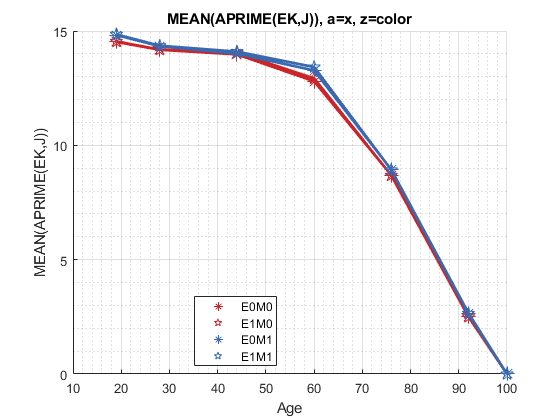

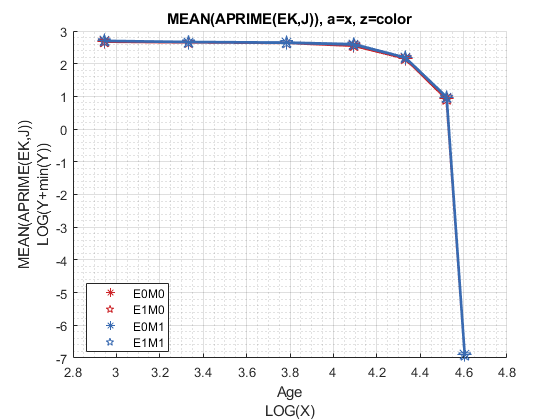

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

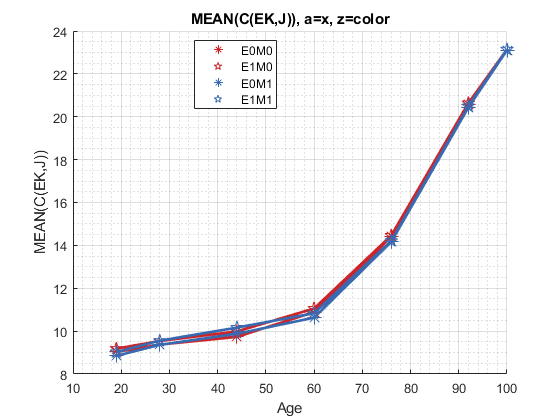

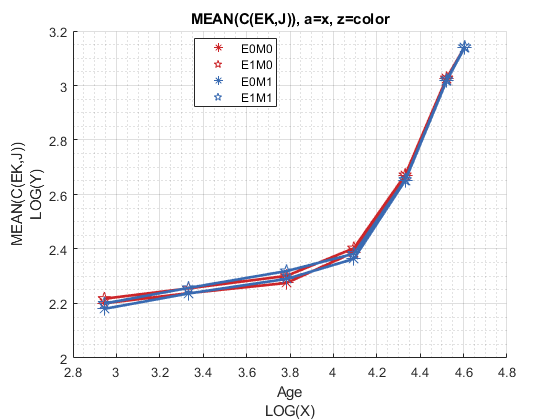

mp_support_graph('cl_st_graph_title') = {'MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);